% Load IEEE 9-bus system data
run('ieee9_A1.m');


%% 1. 
disp('Part 1:');

Part 1:


disp('Testing admittance function...');

Testing admittance function...


Y = admittance(nfrom, nto, r, x, b);

disp('Admittance matrix (Y):');

Admittance matrix (Y):


disp(Y);

   0.0000 -17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3074 -39.3089i  -1.9422 +10.5107i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9422 +10.5107i   3.2242 -15.8409i  -1.2820 + 5.5882i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i  -1.2820 + 5.5882i   2.4371 -32.1539i  -1.1551 + 9.7843i   0.00


% V = IZ 
V = linsolve(Y, Iint);

disp('Voltage (V):');

Voltage (V):


disp(V);

   1.0001 - 0.0001i
   0.9859 + 0.1679i
   0.9966 + 0.0831i
   0.9862 - 0.0415i
   0.9732 - 0.0684i
   1.0029 + 0.0336i
   0.9857 + 0.0106i
   0.9941 + 0.0659i
   0.9550 - 0.0727i




magnitude = abs(V);
angle_rad = angle(V);
angle_deg = angle_rad * (180/pi);

polar_coordinates_rad = [magnitude, angle_rad];
disp('  Magnitude   Angle (in radian)');

  Magnitude   Angle (in radian)


disp(polar_coordinates_rad);

    1.0001   -0.0001
    1.0001    0.1687
    1.0001    0.0832
    0.9871   -0.0421
    0.9756   -0.0702
    1.0035    0.0335
    0.9858    0.0107
    0.9963    0.0662
    0.9578   -0.0760




polar_coordinates_deg = [magnitude, angle_deg];
disp('  Magnitude   Angle (in degree)');

  Magnitude   Angle (in degree)


disp(polar_coordinates_deg);

    1.0001   -0.0060
    1.0001    9.6638
    1.0001    4.7653
    0.9871   -2.4100
    0.9756   -4.0208
    1.0035    1.9178
    0.9858    0.6152
    0.9963    3.7918
    0.9578   -4.3537




%% 2.
disp('Part 2:');

Part 2:


Z = impedance(nfrom, nto, r, x, b);  


disp('Impedance matrix (Z):');

Impedance matrix (Z):


disp(Z);

   0.0103 - 0.6225i  -0.0046 - 0.7614i  -0.0061 - 0.7644i   0.0103 - 0.6801i   0.0032 - 0.7208i  -0.0061 - 0.7644i  -0.0060 - 0.7684i  -0.0046 - 0.7614i   0.0053 - 0.7178i
  -0.0046 - 0.7614i   0.0089 - 0.6194i   0.0001 - 0.7484i  -0.0046 - 0.7614i  -0.0056 - 0.7686i   0.0001 - 0.7484i   0.0047 - 0.7150i   0.0089 - 0.6819i  -0.0029 - 0.7439i
  -0.0061 - 0.7644i   0.0001 - 0.7484i   0.0096 - 0.6249i  -0.0061 - 0.7644i  -0.0037 - 0.7475i   0.0096 - 0.6835i   0.0035 - 0.7268i   0.0001 - 0.7484i  -0.0058 - 0.7691i
   0.0103 - 0.6801i  -0.0046 - 0.7614i  -0.0061 - 0.7644i   0.0103 - 0.6801i   0.0032 - 0.7208i  -0.0061 - 0.7644i  -0.0060 - 0.7684i  -0.0046 - 0.7614i   0.0053 - 0.7178i
   0.0032 - 0.7208i  -0.0056 - 0.7686i  -0.0037 - 0.7475i   0.0032 - 0.7208i   0.0111 - 0.6810i  -0.0037 - 0.7475i  -0.0055 - 0.7656i  -0.0056 - 0.7686i  -0.0004 - 0.7474i
  -0.0061 - 0.7644i   0.0001 - 0.7484i   0.0096 - 0.6835i  -0.0061 - 0.7644i  -0.0037 - 0.7475i   0.0096 - 0.6835i   0.0035 - 0.7268i   0.00


%% 3. 
disp('Part 3:');

Part 3:


disp('Testing on Node 3 for example');

Testing on Node 3 for example


idf = 3;
Zf = 0;

[If, Vf] = fault(Y, Iint, idf, Zf); 

disp('Fault current at node 3 (If):');

Fault current at node 3 (If):


disp(If);

  -0.1084 + 1.5966i



disp('Node voltages during fault (Vf):');

Node voltages during fault (Vf):


disp(Vf);

  -0.2210 - 0.0733i
  -0.2090 + 0.0866i
   0.0000 - 0.0000i
  -0.2349 - 0.1147i
  -0.2207 - 0.1435i
  -0.0873 - 0.0559i
  -0.1743 - 0.0737i
  -0.2008 - 0.0154i
  -0.2736 - 0.1468i



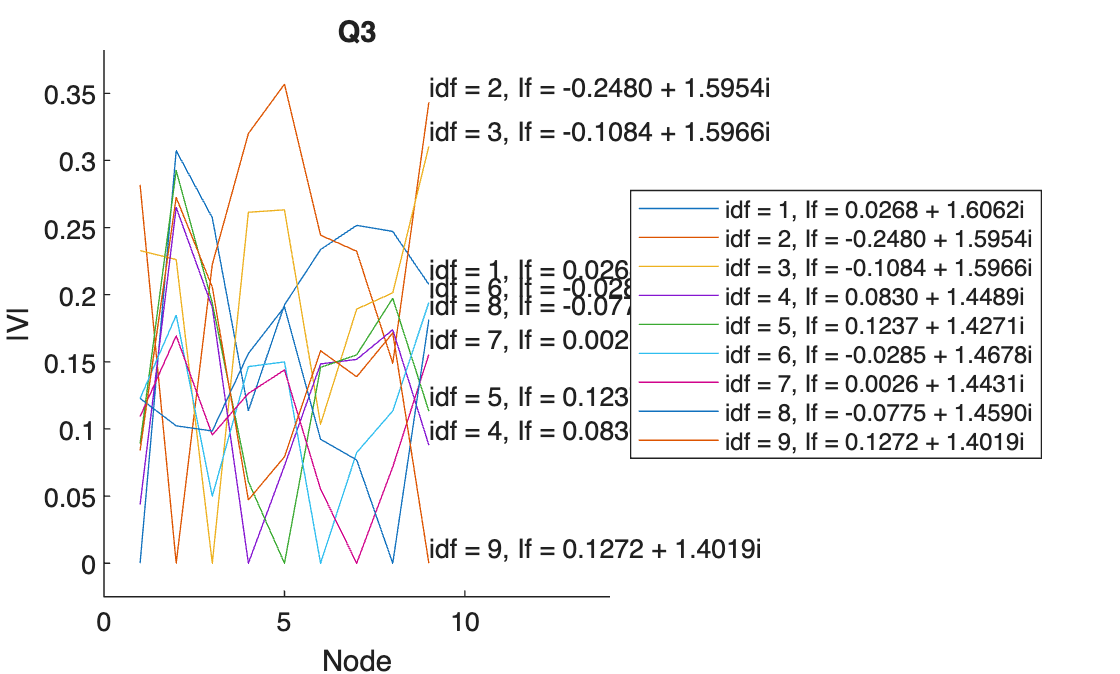


% then we compute for all nodes (lines), and plot them
figure;
hold on;
colors = lines(9);

for idf = 1:9
    [If, Vf] = fault(Y, Iint, idf, Zf);
    Vabs = abs(Vf);
    plot(Vabs, 'Color', colors(idf, :), 'DisplayName', sprintf('idf = %d, If = %.4f + %.4fi', idf, real(If), imag(If)));
    text(length(Vabs), Vabs(end), sprintf('idf = %d, If = %.4f + %.4fi', idf, real(If), imag(If)), 'VerticalAlignment', 'bottom');
end

legend show;
axis padded; 
xlim([0, length(Vabs) + 5]);
legend('Location', 'eastoutside');
xlabel('Node');
ylabel('|V|');
title('Q3');




%% 4. Test generalized Thevenin equivalent function
disp('Part 4:');

Part 4:


disp('a)');

a)


id_thev = [3, 5];  

[Eeq, Zeq] = genthevenin(Y, Iint, id_thev);


disp(['For nodes ', num2str(id_thev)]);

For nodes 3  5


disp('Thevenin equivalent voltages (Eeq):');

Thevenin equivalent voltages (Eeq):


disp(Eeq);

   0.9966 + 0.0831i
   0.9732 - 0.0684i



disp('Thevenin equivalent impedance matrix (Zeq):');

Thevenin equivalent impedance matrix (Zeq):


disp(Zeq);

   0.0096 - 0.6249i  -0.0037 - 0.7475i
  -0.0037 - 0.7475i   0.0111 - 0.6810i






disp('b)');

b)


id_thev = [9, 4]; 

[Eeq, Zeq] = genthevenin(Y, Iint, id_thev);

% Display the Thevenin equivalent voltages and impedance matrix
disp(['For nodes ', num2str(id_thev)]);

For nodes 9  4


disp('Thevenin equivalent voltages (Eeq):');

Thevenin equivalent voltages (Eeq):


disp(Eeq);

   0.9550 - 0.0727i
   0.9862 - 0.0415i



disp('Thevenin equivalent impedance matrix (Zeq):');

Thevenin equivalent impedance matrix (Zeq):


disp(Zeq);

   0.0099 - 0.6803i   0.0053 - 0.7178i
   0.0053 - 0.7178i   0.0103 - 0.6801i




% some additional variables for the plot:
disp('I:');

I:


disp(Iint(9)); % the 9th channel connecting 9-4

  -1.2617 + 0.6186i




disp('delta y:');

delta y:


disp(Y(9,4)); % Y(4,9) works too

  -1.3652 +11.6041i





%% ==========part 5============
%% 5. Test generalized fault calculation function
disp('Part 5:');

Part 5:


disp('a)');

a)


% a) 
disp('Testing generalized fault calculation function...');

Testing generalized fault calculation function...



YN = Y;
% Create fault admittance matrix by removing line between nodes 8 and 9
YF = outage_admittance_helper(YN, nfrom, nto, r, x, b, 8, 9);

disp('YF:');

YF:


disp(YF);

   0.0000 -17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3074 -39.3089i  -1.9422 +10.5107i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9422 +10.5107i   3.2242 -15.8409i  -1.2820 + 5.5882i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i  -1.2820 + 5.5882i   2.4371 -32.1539i  -1.1551 + 9.7843i   0.00



[If, Vf] = fault(YF, Iint, 8, 0);


IintF = Iint;

idN = [8, 9]';
idF = [8, 9]';

[IT, VNF] = genfault(YN, YF, Iint, IintF, idN, idF)

IT =   -0.7024 - 0.0316i
   0.7018 - 0.1357i


VNF =    1.1146 - 0.0305i
   1.1167 + 0.2109i
   1.1288 + 0.0964i
   1.1007 - 0.0719i
   1.0953 - 0.0840i
   1.1351 + 0.0469i
   1.1181 + 0.0413i
   1.1249 + 0.1089i
   1.0619 - 0.1165i



print_magnitudes_angles(IT, VNF, idN, idF);

IT:
line N8-F8: |I| = 0.7031, angle =  -177.42°
line N9-F9: |I| = 0.7148, angle =   -10.94°

VNF:
Line  1: |V| = 1.1150, angle =    -1.57°
Line  2: |V| = 1.1365, angle =    10.69°
Line  3: |V| = 1.1329, angle =     4.88°
Line  4: |V| = 1.1031, angle =    -3.74°
Line  5: |V| = 1.0985, angle =    -4.39°
Line  6: |V| = 1.1361, angle =     2.37°
Line  7: |V| = 1.1189, angle =     2.12°
Line  8: |V| = 1.1302, angle =     5.53°
Line  9: |V| = 1.0683, angle =    -6.26°




% b) 
disp('b)');

b)



idN = [1];
idF = [5];

[IT, VNF] = genfault(YN, YN, Iint, IintF, idN, idF)

IT = -0.0520 + 0.0215i

VNF =    0.9873 - 0.0327i
   0.9693 + 0.1284i
   0.9799 + 0.0434i
   0.9722 - 0.0771i
   0.9579 - 0.1060i
   0.9862 - 0.0061i
   0.9689 - 0.0293i
   0.9775 + 0.0264i
   0.9399 - 0.1102i



print_magnitudes_angles(IT, VNF, idN, idF);

IT:
line N1-F5: |I| = 0.0563, angle =   157.56°

VNF:
Line  1: |V| = 0.9878, angle =    -1.90°
Line  2: |V| = 0.9778, angle =     7.54°
Line  3: |V| = 0.9809, angle =     2.54°
Line  4: |V| = 0.9752, angle =    -4.54°
Line  5: |V| = 0.9638, angle =    -6.31°
Line  6: |V| = 0.9862, angle =    -0.35°
Line  7: |V| = 0.9694, angle =    -1.73°
Line  8: |V| = 0.9779, angle =     1.54°
Line  9: |V| = 0.9463, angle =    -6.69°




% c) 
disp('c)');

c)


idN = [3 5]';
idF = [7 4]'; 

[IT, VNF] = genfault(YN, YN, Iint, IintF, idN, idF)

IT =    0.2727 - 0.0209i
  -0.2835 + 0.0202i


VNF =    1.0042 + 0.0038i
   0.9845 + 0.1542i
   0.9910 + 0.0418i
   0.9903 - 0.0376i
   0.9793 - 0.0579i
   0.9985 + 0.0083i
   0.9830 - 0.0081i
   0.9927 + 0.0522i
   0.9575 - 0.0749i



print_magnitudes_angles(IT, VNF, idN, idF);

IT:
line N3-F7: |I| = 0.2735, angle =    -4.39°
line N5-F4: |I| = 0.2842, angle =   175.93°

VNF:
Line  1: |V| = 1.0042, angle =     0.22°
Line  2: |V| = 0.9965, angle =     8.90°
Line  3: |V| = 0.9918, angle =     2.42°
Line  4: |V| = 0.9910, angle =    -2.17°
Line  5: |V| = 0.9810, angle =    -3.38°
Line  6: |V| = 0.9985, angle =     0.48°
Line  7: |V| = 0.9830, angle =    -0.47°
Line  8: |V| = 0.9941, angle =     3.01°
Line  9: |V| = 0.9605, angle =    -4.48°






% d) 
disp('d)');

d)





% Load IEEE 24-bus system data
run('ieee24_A1.m');

% Create two identical IEEE 24-bus systems
Y = admittance(nfrom, nto, r, x, b);
YN_24 = Y;  % First system (healthy network)
IintN_24 = Iint;  % Current sources for first system

YF_24 = Y;  % Second system (fault network) 
IintF_24 = Iint;  % Current sources for second system

idN = [7 13 23]';
idF = [3 15 17]'; 

[IT_24, VNF_24] = genfault(YN_24, YN_24, IintN_24, IintN_24, idN, idF)

IT_24 =    0.6261 + 0.0548i
  -2.0029 - 0.1361i
   1.7967 + 0.1528i


VNF_24 =    1.0085 - 0.0798i
   1.0079 - 0.0848i
   0.9518 - 0.0263i
   0.9588 - 0.1089i
   0.9952 - 0.1140i
   0.9522 - 0.2270i
   0.9841 - 0.1515i
   0.9497 - 0.1720i
   0.9640 - 0.0617i
   1.0178 - 0.0975i
   0.9835 + 0.0362i
   0.9985 + 0.0522i
   1.0062 + 0.1178i
   0.9638 + 0.0817i
   0.9755 + 0.2760i



print_magnitudes_angles(IT_24, VNF_24, idN, idF);

IT:
line N7-F3: |I| = 0.6285, angle =     5.00°
line N13-F15: |I| = 2.0075, angle =  -176.11°
line N23-F17: |I| = 1.8032, angle =     4.86°

VNF:
Line  1: |V| = 1.0117, angle =    -4.52°
Line  2: |V| = 1.0115, angle =    -4.81°
Line  3: |V| = 0.9522, angle =    -1.58°
Line  4: |V| = 0.9650, angle =    -6.48°
Line  5: |V| = 1.0017, angle =    -6.53°
Line  6: |V| = 0.9788, angle =   -13.41°
Line  7: |V| = 0.9957, angle =    -8.75°
Line  8: |V| = 0.9651, angle =   -10.26°
Line  9: |V| = 0.9660, angle =    -3.66°
Line 10: |V| = 1.0224, angle =    -5.47°
Line 11: |V| = 0.9842, angle =     2.11°
Line 12: |V| = 0.9999, angle =     2.99°
Line 13: |V| = 1.0131, angle =     6.68°
Line 14: |V| = 0.9672, angle =     4.85°
Line 15: |V| = 1.0138, angle =    15.80°
Line 16: |V| = 1.0152, angle =    14.71°
Line 17: |V| = 1.0417, angle =    19.15°
Line 18: |V| = 1.0552, angle =    20.41°
Line 19: |V| = 1.0163, angle =    12.15°
Line 20: |V| = 1.0297, angle =    11.86°
Line 21: |V| = 1.0562, angle =    




disp('All tests completed successfully.');

All tests completed successfully.
